Filtro de Kaiman para aceleração discreta

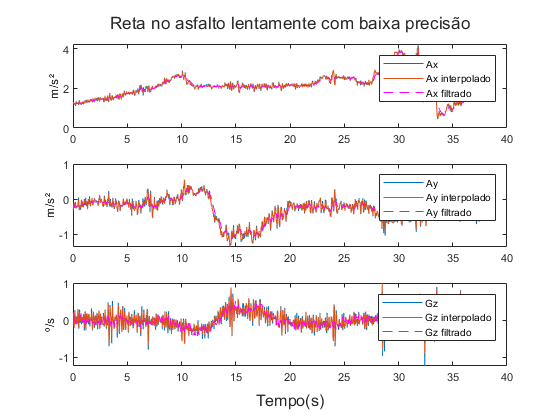

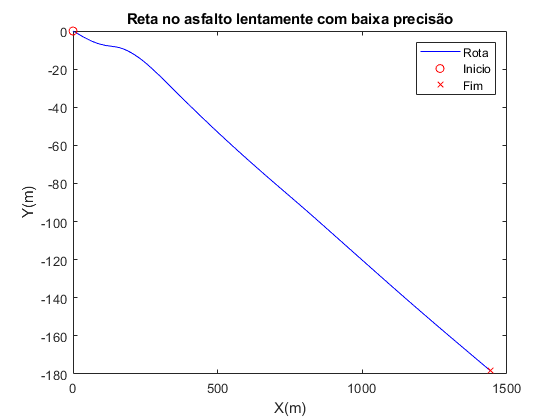

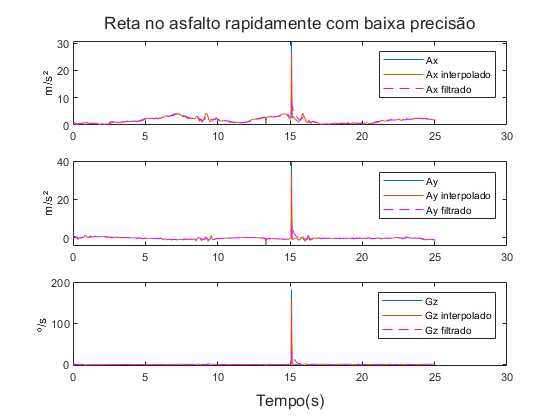

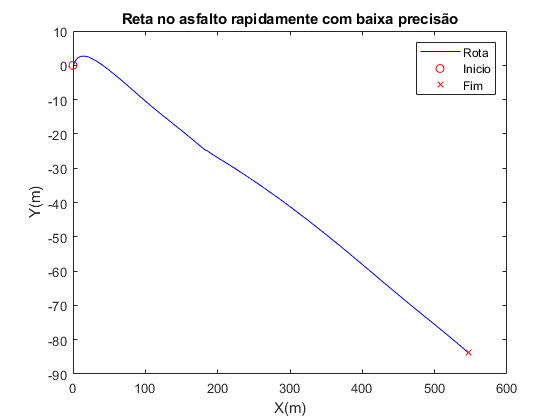

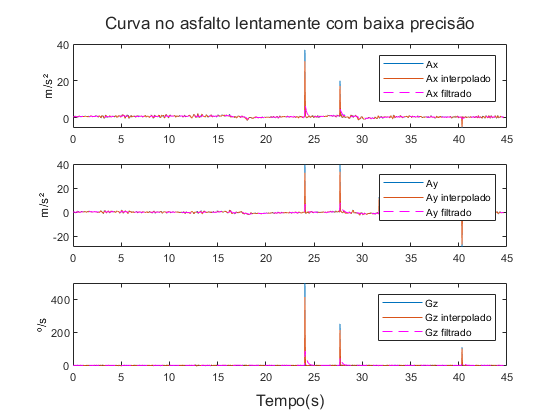

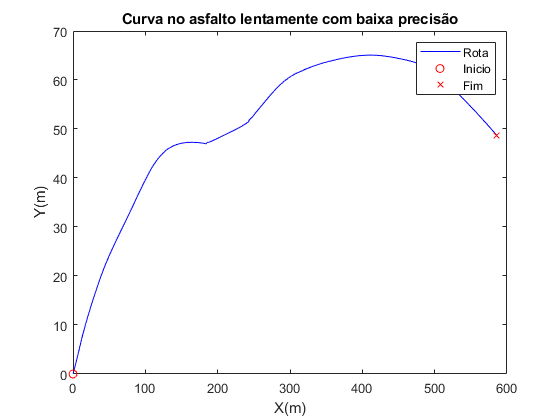

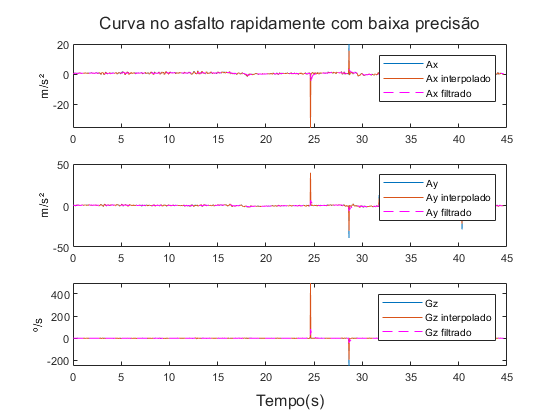

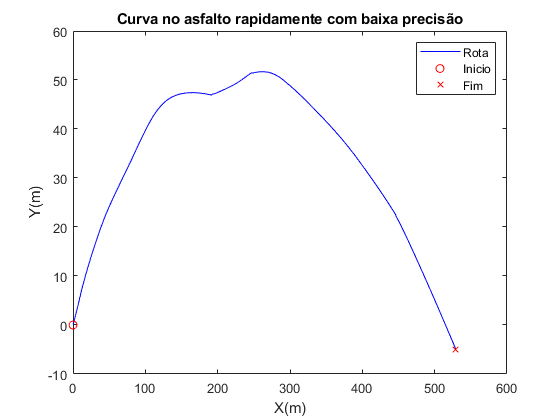

clear;
load('Leitura.mat');
load('calibracao.mat');
tamanho = length(medicoes);
sufixo = [""," interpolado"," filtrado"];
prefixo = ["Ax", "Ay", "Gz"];
legenda = arrayfun(@(x) arrayfun(@(y) x+y,sufixo),prefixo,'UniformOutput',false);
for i=1:tamanho
    %inicializando
    Ax=medicoes(i).valores.Ax;
    Ay=medicoes(i).valores.Ay;
    Gz=medicoes(i).valores.Gz;
    %interpolando para intervalo de amostragem padrao
    Tempo=medicoes(i).valores.Ms/1000;
    dT_amostragem=mean(diff(Tempo));
    Tempo_amostragem = Tempo(1):dT_amostragem:Tempo(end);
    Axm=interp1(Tempo,Ax,Tempo_amostragem);
    Aym=interp1(Tempo,Ay,Tempo_amostragem);
    Gzm=interp1(Tempo,Gz,Tempo_amostragem);
    %filtro na interpolação
    tamanho2 = length(Axm);
    Axf=Kalman1DInt(dT_amostragem,Axm,false);
    Ayf=Kalman1DInt(dT_amostragem,Aym,false);
    Gzf=Kalman1DInt(dT_amostragem,Gzm,true);
%     kalman=Kalman2DInt(dT_amostragem,Axm,Aym,Gzm);
%     Axf=kalman.Ax;
%     Ayf=kalman.Ay;
%     Gzf=kalman.Gz;
    %plotagem
    figure();
    fig=tiledlayout(3,1);
    fig.Title.String=TituloRota(medicoes(i).R,medicoes(i).A);
    nexttile
    plot(Tempo,Ax,Tempo_amostragem,Axm,Tempo_amostragem,Axf.Accel,'--magenta');
%     plot(Tempo,Ax,Tempo_amostragem,Axm,Tempo_amostragem,Axf,'--magenta');
    legend(legenda{1});
    ylabel("m/s²");
    nexttile
    plot(Tempo,Ay,Tempo_amostragem,Aym,Tempo_amostragem,Ayf.Accel,'--magenta');
%     plot(Tempo,Ay,Tempo_amostragem,Aym,Tempo_amostragem,Ayf,'--magenta')
    legend(legenda{2});
    ylabel("m/s²");
    nexttile
    plot(Tempo,Gz,Tempo_amostragem,Gzm,Tempo_amostragem,Gzf.Gyro,'--magenta');
%     plot(Tempo,Gz,Tempo_amostragem,Gzm,Tempo_amostragem,Gzf,'--magenta')
    legend(legenda{3});
    ylabel("º/s");
    xlabel(fig,"Tempo(s)");
    %trajectory
    figure();
    X=Axf.Deslocamento;
    Y=Ayf.Deslocamento;
    Yaw= Gzf.Angulo;
%     X=kalman.Px;
%     Y=kalman.Py;
%     Yaw=kalman.Oz;
    plot(X,Y,'blue',X(1),Y(1),'or',X(end),Y(end),'xr');
    title(fig.Title.String);
    xlabel('X(m)');
    ylabel('Y(m)');
    legend('Rota','Inicio','Fim');
end

function titulo=TituloRota(R,A)
    titulo= "";
    switch R
        case 1
            titulo = titulo + "Reta no asfalto lentamente ";
        case 2
            titulo = titulo + "Reta no asfalto rapidamente ";
        case 3
            titulo = titulo + "Curva no asfalto lentamente ";
        case 4
            titulo = titulo + "Curva no asfalto rapidamente ";
        case 5
            titulo = titulo + "Reta no chão lentamente ";
        case 6
            titulo = titulo + "Reta no chão rapidamente ";
        case 7
            titulo = titulo + "Curva no chão lentamente ";
        case 8
            titulo = titulo + "Curva no chão rapidamente ";
    end
    switch A
        case 1
            titulo =titulo + "com baixa precisão";
        case 4
            titulo =titulo + "com alta precisão";
    end
end

function Xk=Kalman1D(dT,f,isAngle,qm,rm)
if nargin == 3
    rm=1;
    qm=1;
elseif nargin ==4
    rm=1;
end
    %incializa
    tamanho=length(f);
    Xk=zeros(1,tamanho);
    Pk_prev=1;
    Xk_prev=0;
    R=randn(1,tamanho);
    Q=randn(1,tamanho);
    if isAngle
        rvar=0.05^2;
    else
        rvar = (400*9.81*1e-6)^2 *dT;
    end
    qvar=rvar*dT;
    for i=1:tamanho
        R(i)= R(i) * rvar * rm;
        Q(i)= Q(i) * qvar * qm;
        %predict
        X_pred= Xk_prev;
        P_pred = Pk_prev + Q;
        Kk=P_pred/(P_pred+R);
        %update
        Xk(i)=X_pred+(Kk*(f(i)-X_pred));
        Pk=(1-Kk)*P_pred;
        if isAngle
            Xk(i)=rem(Xk(i),360);
            Pk=rem(Pk,360);
        end
        
        Xk_prev=Xk(i);
        Pk_prev=Pk;
    end
end

function dados=Kalman1DInt(dT,f,isAngle,qm,rm)
%kalman 1d com integração
    if nargin == 3
        rm=1;
        qm=1;
    elseif nargin ==4
        rm=1;
    end
    %incializa
    tamanho=length(f);
    if isAngle
        %xk=[gz; oz]
        Xk=zeros(2,tamanho);
        Xk_prev=zeros(2,1);
        X_pred=Xk_prev;
        H=[1,0];
        A=[1,0;dT,1];
        Pk_prev=eye(2);
        I=eye(2);
        vvar=0.05;
        wvar=[vvar;vvar*dT];
        n=2;
        
    else
        %xk=[a;v;p]
        Xk=zeros(3,tamanho);
        Xk_prev=zeros(3,1);
        X_pred =Xk_prev;
        H=[1,0,0];
        A=[1,0,0;dT,1,0;dT^2 /2, dT,1];
        Pk_prev=eye(3);
        I=eye(3);
        vvar=400*9.81*1e-6 *sqrt(dT);
        wvar=[vvar;vvar*dT;vvar*dT^2 /2];
        n=3;
    end
    Q=wvar*wvar.' * dT;
    R=vvar^2;
    for i=1:tamanho
        z=f(i);
        v=randn(1) * vvar;
        w=randn(n,1) .* wvar;
        %predicao
        X_pred=A*Xk_prev+w;
        P_pred=A*Pk_prev*(A.')+Q;
        %atualização
        Kk=P_pred*(H.')/(H*P_pred*(H.')+R);
        Xk(:,i)=X_pred+Kk*(z-H*X_pred - v);
        Pk=(I-Kk*H)*P_pred*((I-Kk*H).')+Kk*R*(Kk.');
        if isAngle %impede overflow de grau
            Xk(:,i)=rem(Xk(:,i),360);
            Pk=rem(Pk,360);
        end
        Xk_prev=Xk(:,i);
        %anteriores
        Pk_prev=Pk;
    end
    if isAngle
        dados=array2table(Xk.','VariableNames',{'Gyro','Angulo'});
    else
        dados=array2table(Xk.','VariableNames',{'Accel','Velocidade','Deslocamento'});
    end
end

function dados = Kalman2DInt(dT,Ax,Ay,Gz,qm,rm)
    if nargin == 4
        rm=1;
        qm=1;
    elseif nargin ==5
        rm=1;
    end
    tamanho=length(Ax);
    %inicializando
    Xk=zeros(14,tamanho);
    Xk_prev= zeros(14,1);
    Pk_prev=eye(14);
    H=zeros(3,14);
    I=eye(14);
    index = sub2ind(size(H),[1 2 3],[1 4 7]);
    H(index) = 1;
    %covariancias
    std_a=400*1e-6 *9.81 * sqrt(dT);
    std_g=0.05;
    vvar= [std_a;std_a;std_g];
    wvar=Kalman2Dwstd(std_a,std_g,dT);
    Q=wvar * (wvar.') * dT * qm;
    R=vvar * (vvar.') * rm;
    %loop
    for i=1:tamanho
        %atualizando variaveis
        z=[Ax(i);Ay(i);Gz(i)];
        w=randn(14,1) .* wvar;
        v=randn(3,1) .* vvar;
        A=Kalman2DA(Xk_prev,dT);
        %predicao
        X_pred = A*Xk_prev + w;
        P_pred=A*Pk_prev*(A.')+Q;
        %atualizacao
        K=P_pred * (H.') / (H*P_pred*(H.')+ R);
        Xk(:,i)=X_pred+ K*(z-H*X_pred-v);
        Pk=(I - K*H)*P_pred*((I-K*H).')+ K*R*(K.');
        %impedindo overflow do angulo
        Xk(8,i) = rem(Xk(8,i),360);
        Pk(8,:) = rem(Pk(8,:),360);
        Pk(:,8) = rem(Pk(:,8),360);
        %atualiza anteriores
        Xk_prev=Xk(:,i);
        Pk_prev = Pk;
    end
    variaveis = {'Ax','Vx','Px','Ay','Vy','Py','Gz','Oz'...
        ,'Axr','Vxr','Pxr','Ayr','Vyr','Pyr'};
    dados=array2table(Xk.',"VariableNames",variaveis);
end

function wvar=Kalman2Dwstd(stda,stdg,dT)
    accel_std=[1;dT;dT^2 /2]*stda;
    gyro_std=[1;dT]*stdg;
    rotx=cosd(stdg*dT) - sind(stdg*dT);
    roty=cosd(stdg*dT) + sind(stdg*dT);
    wvar=[accel_std;accel_std;gyro_std;accel_std*rotx;accel_std*roty];
end

function A=Kalman2DA(xk_1,dT)
    %assumindo X 14x1
    % 1ax 2vx 3px 4ay 5vy 6py 7gz 8oz 9axr 10vxr 11pxr 12ayr 13vyr 14pyr] 
    A=eye(14);
    mat_accel = [1,0,0;dT,1,0;dT^2 /2,dT,1];
    mat_gyro = mat_accel(1:2,1:2);
    yaw = mat_gyro(2,:) * xk_1(7:8,:); %rotacao em z em relação ao inicio
    rotacao = eul2rotm([deg2rad(-yaw),0,0],'ZYX'); %desfazendo a rotação
    %para ter aceleracao nos eixos do mundo
    rotacao=rotacao(1:2,1:2);
    mat_asr=mat_accel(1:3,1);
    mat_asr=[mat_asr,zeros(3,1);zeros(3,1),mat_asr];
    P=[1,zeros(1,13);0,0,0,1,zeros(1,10)];
    mat_ar=mat_asr*rotacao*P;
    index=sub2ind(size(A),[9 12],[9 12]);
    A(index)=0;
    A(1:3,1:3)=mat_accel; %ax vx px
    A(4:6,4:6)=mat_accel; % ay vy py
    A(9:14,:)=mat_ar; % axr vxr pxr ayr vyr pyr
    A(7:8,7:8)=mat_gyro; % gz oz
end